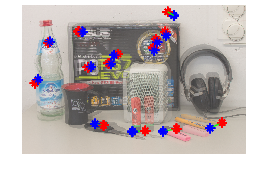

%% Load images
Image1 = imread('sceneL.png');
IGray1 = rgb_to_gray(Image1);
Image2 = imread('sceneR.png');
IGray2 = rgb_to_gray(Image2);

%% Calculate Harris features
features1 = harris_detector(IGray1,'segment_length',9, ...
    'k',0.05,'min_dist',40,'N',50,'do_plot',false);
features2 = harris_detector(IGray2,'segment_length',9, ...
    'k',0.05,'min_dist',40,'N',50,'do_plot',false);

%% Correspondence estimation
correspondences = point_correspondence(IGray1,IGray2, ...
    features1,features2,'window_length',25,'min_corr',0.9,'do_plot',false);

%% Determine robust corresponding image points with the RANSAC algorithm
correspondences_robust =  ...
    F_ransac(correspondences, 'tolerance', 0.04);

%% Visualize robust corresponding image points
figure(1)
imshow(Image1);
hold on
imshow(Image2);
hold on
alpha(0.5);  % add transparancy of 50%
for i=1:size(correspondences_robust,2)
    plot(correspondences_robust(1,:), correspondences_robust(2,:), ...
        'r*', 'MarkerSize', 6, 'LineWidth',1);
    plot(correspondences_robust(3,:), correspondences_robust(4,:), ...
        'b*', 'MarkerSize', 6, 'LineWidth',1);
    plot([correspondences_robust(1,i),correspondences_robust(3,i)], ...
        [correspondences_robust(2,i),correspondences_robust(4,i)], 'g-', 'LineWidth',1);
    hold on
end


%% Calculate essential matrix
K = 1000* [8.2853         0    1.5412;
         0    8.3024    1.4397;
         0         0    0.0010;]

K = 1.0e+03 *

    8.2853         0    1.5412
         0    8.3024    1.4397
         0         0    0.0010


E = epa(correspondences_robust, K);
disp(E);

   -0.0647   -0.7814   -0.1289
    0.7100   -0.0999    0.6907
    0.0346   -0.6131   -0.0171





[T1, R1, T2, R2, ~, ~] = TR_from_E(E)

T1 =     0.6071
    0.0938
   -0.7891


R1 =    -0.1383    0.1723   -0.9753
    0.0356   -0.9832   -0.1788
   -0.9897   -0.0595    0.1299


T2 =    -0.6071
   -0.0938
    0.7891


R2 =     0.9887   -0.1003    0.1116
    0.0957    0.9944    0.0454
   -0.1155   -0.0342    0.9927



[T, R, lambda, M1, M2] = reconstruction(T1, T2, R1, R2, correspondences_robust, K);

size(lambda)

ans =     14     2


size(M1)

ans =     42    15


size(M2)

ans =     42    15



% Show euclidian transformation
fprintf('Rotation Matrix:\n');

Rotation Matrix:


fprintf('%+5.3f %+5.3f %+5.3f\n',R');

+0.989 -0.100 +0.112
+0.096 +0.994 +0.045
-0.116 -0.034 +0.993


fprintf('\nTranslation Vektor:\n');


Translation Vektor:


fprintf('%+4.2f\n',T);

-0.61
-0.09
+0.79
